# A Poisson problem with nonhomogeneous vertex conditions

Set up a quantum graph in the form of a dumbbell plus one extra edge

Solve the vertex-value problem 


$$\triangle u = f \\
\sum u'(\mathtt{v_1})+ u(\mathtt{v_1}) = 1 \\
\sum u'(\mathtt{v_2})+ u(\mathtt{v_2}) = 2 \\
u(\mathtt{v_3}) = 3

$$


where 

- The functions on the right-hand-sides are $f = \left\{\cos{x}, x, \sin{2x}, 1 \right\}$on the four edges.

- the edges have lengths $\left\{
2\pi, 4, 2\pi, 1
\right\}$.

- The exact solutions on the edges are $\left\{
\frac{19}{2}-\cos{x}, 
\frac16 ( 51 -45 x + x^3),
 \frac{1}{12}(-130 - 3 \sin{2x}, 
\frac{1}{6} (-65 + 80 x + 3 x^2 )
\right\}$.

Exact solution computed in accompanying Mathematica notebook of the same name.

## Quantum graph definition

s=[1 1 2 2];
t=[1 2 2 3];
L=[2*pi 4 2*pi 1];
robinCoeff=[1 1 nan];

## The exact solution

u1=@(x)(19/2-cos(x));
u2=@(x)(51-45*x+x.^3)/6;
u3=@(x)(-130-3*sin(2*x))/12;
u4=@(x)(-65+80*x+3*x.^2)/6;

## The right hand sides

Edges and nodes

f1=@(x)cos(x);
f2=@(x)x;
f3=@(x)sin(2*x);
f4=1;
nodeData = (1:3)';

## Solve the system twice,

doubling the number of discretization points between the two runs.

nx = [16 32];
errors=zeros(1,2);
for k=1:2

Define the quantum graph (all that changes between the two iterates is the number of discretization points per unit length).

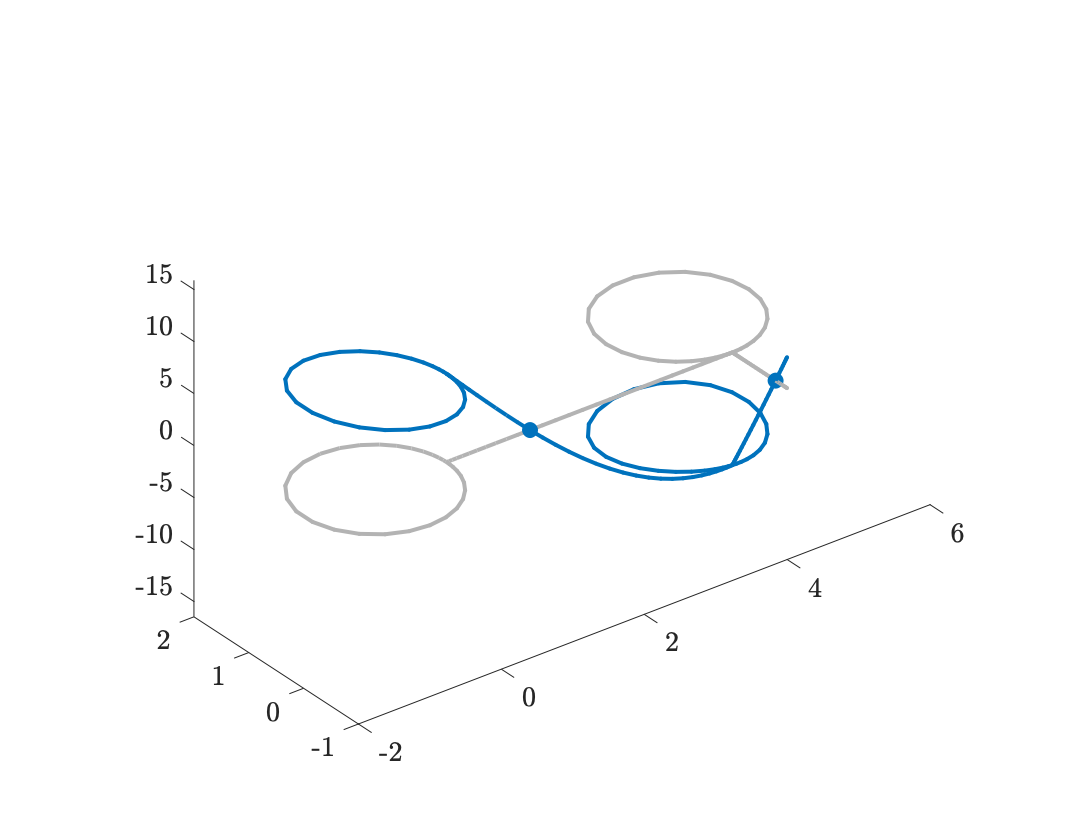

    Phi=quantumGraph(s,t,L,'RobinCoeff',robinCoeff,'nxVec',nx(k),...
        'nodeData',nodeData,'Discretization','Chebyshev');

Set up the exact solution on the edges

    exactSolution = Phi.applyFunctionsToAllEdges({u1,u2,u3,u4});

The error with N=16 is 2.0752e-08.


Set up the nonhomogeneous data on the edges

    edgeData = Phi.applyFunctionsToAllEdges({f1,f2,f3,f4});

The error with N=32 is 1.4603e-11.


Solve and compute errors

    numericalSolution = Phi.solvePoisson('edgeData',edgeData);

The maximum error went down by a factor of 1421.0133.


    errors(k)= max(abs(exactSolution-numericalSolution));
end

Plot the solution

Phi.addPlotCoords(@poissonExamplePlotCoords);
Phi.plot(numericalSolution)

Display the reduction in error. Since the discretization is second order, this should be about a faction of four.

fprintf('The error with N=16 is %0.4d.\n',errors(1))
fprintf('The error with N=32 is %0.4d.\n',errors(2))
fprintf("The maximum error went down by a factor of %0.4f.\n", errors(1)/errors(2) )